# Fourier Analysis of Signals Using DFT 

Let $x[n] =  A_0\cos(w_0n) +  A_1\cos(w_1n), n \in \mathbb{Z}$ be the discrete-time signal obtained by sampling $x(t)$with sampling frequency $T_s$. 

Write down expressions for $x(t)$:

Let us assume that we have $x[n]$values available for $0\leq n\leq L-1$only using which we are required to do frequency analysis. We assume that $x[n]=0$ for $n\notin \{0,L-1\}$.  That is, we have the windowed sequence, $v[n]$, defined as follows:$v[n] = x[n]w[n]$, where $w[n] = 1$for $0\leq n\leq L-1$ and $w[n] =0$, otherwise. This window is called as the rectangular window. 

#### Coding Question

Write a code to get $x[n], w[n] $and $v[n]$

`Refer to python file for this`

#### Coding Question 

Compute $N$-point DFT, $V[k]$ of $v[n]$ and plot $V[k]$ from $k\in [0, N-1]$

`Refer to python file for this`

It is bit difficult to read the above plots as we do not readily see which samples correspond to which discrete-time frequency. Hence, let us try to view the DTFT of v[n] (approximate). Let us first compute the DTFT of $w[n]$.

#### Coding Question 

Compute the DTFT of w[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

 `Refer to python file for this`

#### Coding Question 

Compute the DTFT of v[n] and display its magnitude and phase response in $[-\pi,\pi]$. 

`Refer to python file for this`

#### Coding Question 

Now, suppose the $x(t)$ was sampled at sampling period of $T_s$, then plot $X(j\Omega)$, your estimate of the continuous-time Fourier transform of $x(t)$. 

`Refer to python file for this`

#### Inference Question 

Now, repeat the above four questions for 

- 
$$w_0 = 2\pi/14, w_1 = 2\pi/15$$


- 
$$w_0 = 2\pi/14, w_1 = 2\pi/12$$


- 
$$w_0 = 2\pi/14, w_1 = 4\pi/25$$


`Refer to python file for this`

- What do you observe on the number of peaks?  

- How does your observation change if you change $L$? 

- How does your observation change if you change $N$? 

- Do the amplitudes of $|V[k]|$reflect that of $|V(e^{j\omega})|$? Why? 

- Do the amplitudes of $|V(e^{j\omega})|$ reflect that of $|X(e^{j\omega})|$?  Why? 

1)Number of peaks decreases as w decreases

2)On changing L, the output spectrum remains same given the periodicity, the curve becomes smooth and peaks come close.

3)On changing N, nothing much changes, you just get more sample of the continuous DTFT

4)YES, because DFT is just a sampled version of the DTFT, where DFT is discrete and DTFT is continous 

5)Yes, because V(w) is the time domain sampled and time limited version of the analog signal X(w)

## Short-Time Fourier Transform

Previously we assumed that the frequencies and amplitudes of the sinusoids do not change with time. However, in practice, usually amplitudes and frequencies of a signal change with time. For analyzing the frequency content of that we consider only a small window and analyse its frequency content, and slide the window to look at the frequency content of the next window and so on. This is called the Short-Time Fourier Transform. 

Read the first page of Section 10.3 of "Discrete-Time Signal Processing", 2nd Edition by Alan V. Oppenheim, Ronald Schafer and John R. Buck. 

- How is the short-time Fourier transform defined as, for a sequence $x[n]$.

        ANSWER:  The short-time Fourier transform (STFT) is used to analyze how the frequency content of a nonstationary signal changes over time. We pause the signal at a certain time instant and then consider the signal over a window and then perform the required Fourier analysis on this window.

- Now, construct the following frequency modulated chirp signal: $x[n] = \cos(\omega_0 n^2), $ where $\omega_0 = 2\pi\times 7.5\times10^{-6}. $

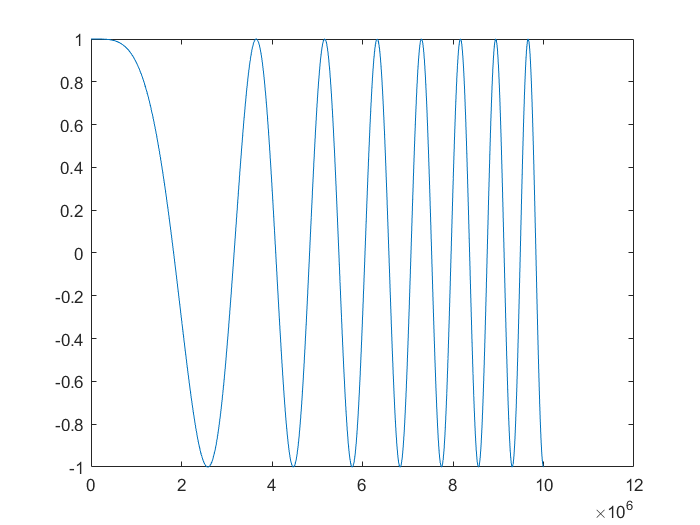

%Frequency modulated chirp signal

fs = 10e3;  %sampling frequency
t = 0:1/fs:1e3;
wo = 7.5*10^-6; %omega
x = cos(2*pi*wo*t.*t); %frequency modulated signal

%plotting the function to see the varying frequency
plot(x);

- Now compute the short-term Fourier transform of $x[n], $ with rectangular window, $w[n]$  of some L  length. 

Reference for STFT code: [https://in.mathworks.com/matlabcentral/fileexchange/45197-short-time-fourier-transform-stft-with-matlab?s_tid=mwa_osa_a](https://in.mathworks.com/matlabcentral/fileexchange/45197-short-time-fourier-transform-stft-with-matlab?s_tid=mwa_osa_a)

% define analysis parameters
wlen = 1024;                        % window length
hop = wlen/4;                       % hop size/ jump
nfft = 4096;                        % number of fft points in stft function

% perform STFT
win = rectwin(wlen);    %rectangular window function with length as parameter

%STFT using the function
[S, f, t] = stft(x, win, hop, nfft, fs)

S = 	1.0e+03 *

   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i   1.0240 + 0.0000i
   0.6524 - 0.6514i   0.6524 - 0.

f = 	1.0e+03 *

         0    0.0024    0.0049    0.0073    0.0098    0.0122    0.0146    0.0171    0.0195    0.0220    0.0244    0.0269    0.0293    0.0317    0.0342    0.0366    0.0391    0.0415    0.0439    0.0464    0.0488    0.0513    0.0537    0.0562    0.0586    0.0610    0.0635    0.0659    0.0684    0.0708    0.0732    0.0757    0.0781    0.0806    0.0830    0.0854    0.0879    0.0903    0.0928    0.0952    0.0977    0.1001    0.1025    0.1050    0.1074    0.1099    0.1123    0.1147    0.1172    0.1196


t =     0.0512    0.0768    0.1024    0.1280    0.1536    0.1792    0.2048    0.2304    0.2560    0.2816    0.3072    0.3328    0.3584    0.3840    0.4096    0.4352    0.4608    0.4864    0.5120    0.5376    0.5632    0.5888    0.6144    0.6400    0.6656    0.6912    0.7168    0.7424    0.7680    0.7936    0.8192    0.8448    0.8704    0.8960    0.9216    0.9472    0.9728    0.9984    1.0240    1.0496    1.0752    1.1008    1.1264    1.1520    1.1776    1.2032    1.2288    1.2544    1.2800    1.3056


- Now use [spectrogram](https://in.mathworks.com/help/signal/ref/spectrogram.html) to compute the short-time Fourier transform of the above $x[n]$ and compare it with what you had got. 

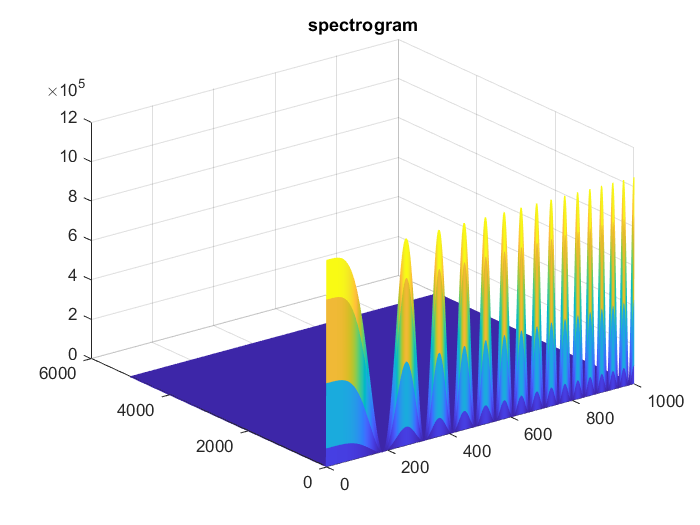

%inbuilt function spectrogram
S_calc = spectrogram(x, win, hop, nfft, fs);


%plotting spectrogram
mesh(t,f,abs(S).^2)
title("spectrogram")

# Practical Experiment

- Now count 1 to 5 in any language of your interest (try your mother tongue) and record it.

Check for the matlab file named "**practicalexperiment.m"**

- Now compute the spectrogram of the signal you have recorded

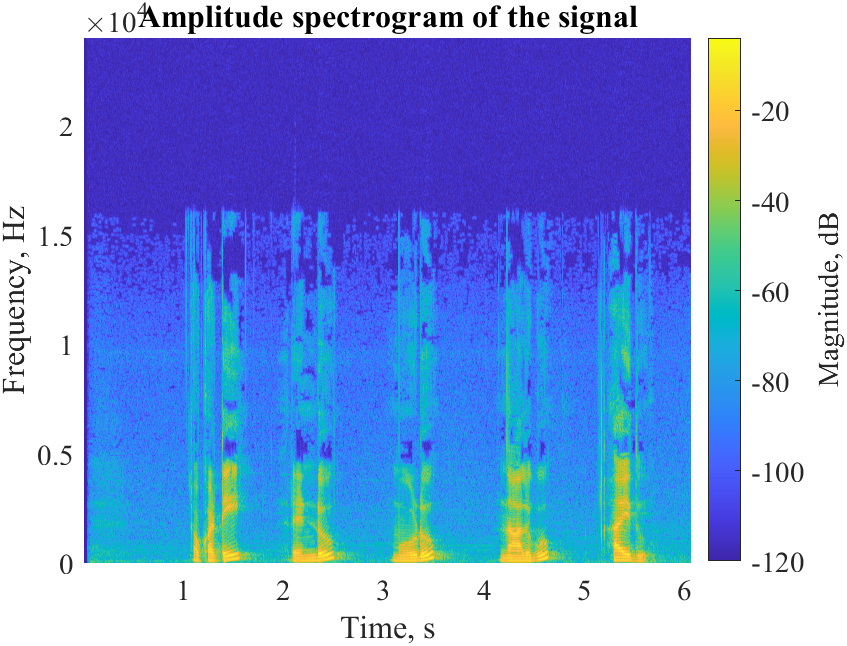

Check for the matlab file named "**practicalexperiment.m"**

- Play with different parameters of the spectrogram and write your 3 observations: 

We can observe in spectrogram that the time varying system and excitation characteristics, since we counted 5 numbers and the sound signal contains high power during that instants only, which is verified by the amplitude spectrogram.

        ANSWER: Check for the matlab file named "**practicalexperiment.m"**

- Now compute the [periodogram](https://in.mathworks.com/help/signal/ref/periodogram.html) of the recorded signal:

Check for the matlab file named "**practicalexperiment.m"**

- What information does the periodogram give? 

        ANSWER:  Periodogram gives us the spectral power density of the signal. We can see what range of the signal correspond to most power and what range of the signal is of neglible power through a periodogram, as a function of frequency.

- Until what frequency does human voice contain significant power density? 

        ANSWER: 

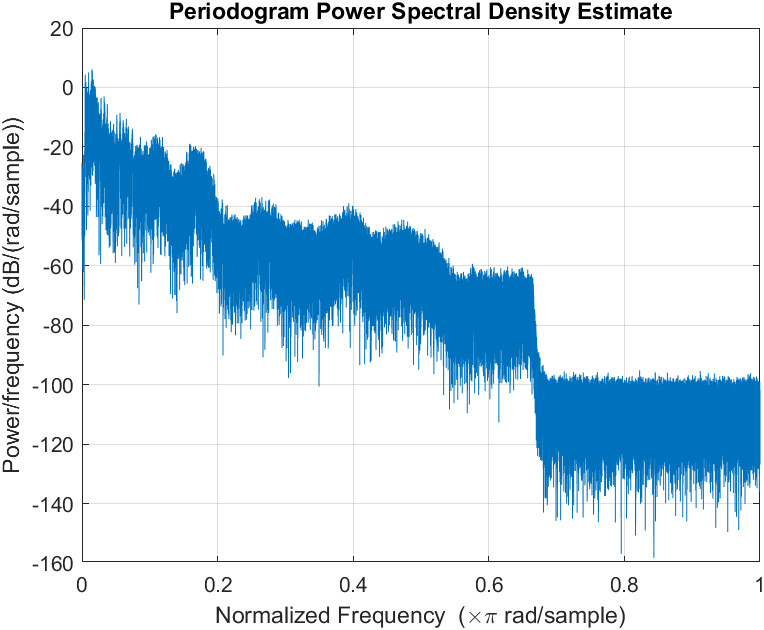

From 0 to 0.2 $\pi$, the power is concentrated and the power goes down to upto -140 dB for the next frequency components.

# Design and Comparison of FIR and IIR Filters 

Design and compare FIR and IIR filters. Refer to the below diagram for the lab.  

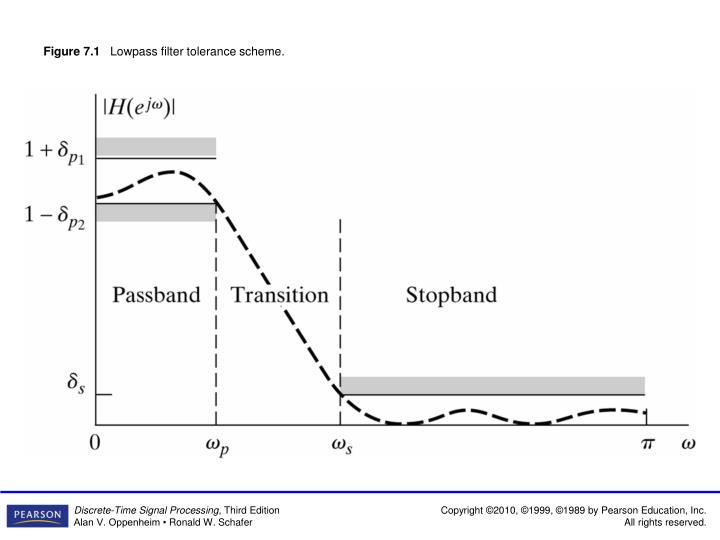

## FIR Filter Design 

Now, we will design FIR filters satisfying the following specifications: 

- 
$$\omega_p =0.4\pi
$$


- 
$$\omega_s = 0.6\pi
$$
 

- 
$$\delta_{p_1}=\delta_{p_2}=0.01, \;\;\delta_s=0.01$$


### Windowing Method

Now, using the Kaiser window, design  window-based FIR filter with the above specifications 

- What is the filter order (approx)?  $\textrm{ENTER}\;\textrm{YOUR}\;\textrm{ANSWER}\;\textrm{HERE}$

- Open "filterDesigner" tool (you can open it by typing *filterDesigner* in the Matlab command window as shown below.)

                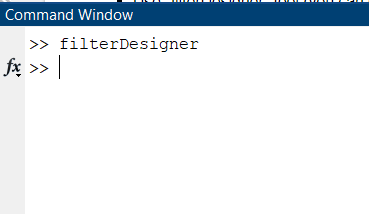

       Open the below view. Here you can specify frequency and magnitude specifications. 

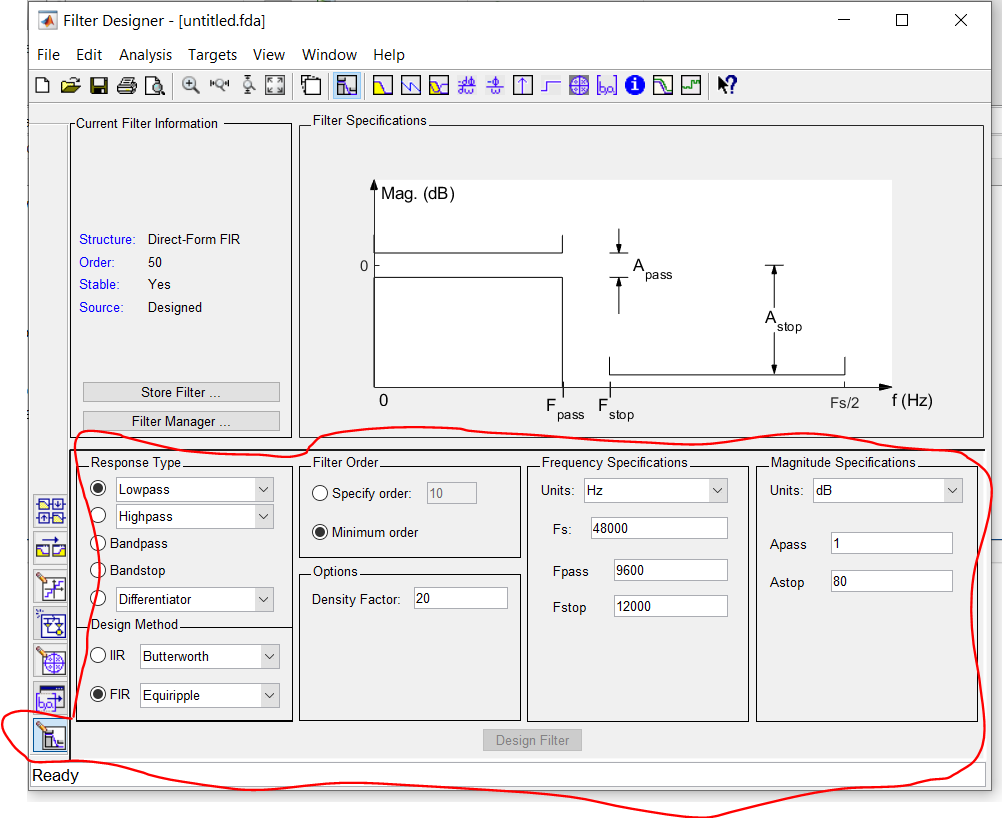

-   Obtain the coefficients of the filter. Write down the coefficients below. 

% ASSIGN THE FILTER COEFFICIENTS TO "b". 
coefficients = [-0.0029   
    -0.0049    
    0.0076    
    0.0110   
    -0.0155   
    -0.0214    
    0.0292    
    0.0401   
    -0.0565   
    -0.0845    
    0.1470    
    0.4507    
    0.4507    
    0.1470   
    -0.0845   
    -0.0565   
    0.0401    
    0.0292   
    -0.0214   
    -0.0155    
    0.0110    
    0.0076   
    -0.0049   
    -0.0029 ];

- Does the number of entries in $b$ correspond to the above theoretically obtained (by you) filter order ?

           * ANSWER:*

**Stop band attenuation is -40dB and the transition lobe width is 0.2**$\omega$**, so the kaiser window length will be,**

    
$$n=\frac{\alpha -8\;}{2\ldotp 285\;\Delta \omega }+1$$
 

**so by substituting the values we get,**

**n = 23.28 ~ 23, which is obtained by the filterDesigner function also.**

- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.  

           * ANSWER:*

The magnitude response is as expected and has 0 dB in pass band and max gain of -40dB in the stop band, whereas the phase response is piecewise linear function with frequency.

The pole-zero plot has 23 zeros and 1 pole at origin of the z-plane, which is given by the 24(23 zeros, 1 pole) coefficients from the filter designed.

The Group delay obtained is 11.5 samples, which matches with M/2 = 23/2 acccordingly for all the frequencies.

### Min-Max Method : 

You already know that the the FIR filter designed using the windowing method has minimimum mean squared error with respect to the ideal filter response. Now, we will design a filter which minimizes the maximum error with respect to the ideal filter. Design an FIR filter satisfying the specifications using  [firpm](https://in.mathworks.com/help/signal/ref/firpm.html).

% WRITE YOUR CODE HERE
delta_pass = 0.01 ; %ripple in passband 
delta_stop = 0.01 ; %ripple in stopband
w_p = 0.4*pi ; %passband edge
w_s = 0.6*pi ; %stopband edge

%transition lobe width
M = 23 

M = 23


%define the frequency range
F = [0 w_p w_s pi]/pi;
A = [1 1 0 0]; %As we want unit gain in passband and 0 gain in stopband 
W = [1 delta_pass/delta_stop]; %weighting factor 
b = firpm(M,F,A,W);
fvtool(b,1) %for the filter visualization tool 
%filter coefficients of the firpm function
disp(b)

  Columns 1 through 11

   -0.0032   -0.0064    0.0086    0.0109   -0.0159   -0.0213    0.0297    0.0398   -0.0567   -0.0839    0.1469

  Columns 12 through 22

    0.4486    0.4486    0.1469   -0.0839   -0.0567    0.0398    0.0297   -0.0213   -0.0159    0.0109    0.0086

  Columns 23 through 24

   -0.0064   -0.0032



- Observe the pole-zero plot, magnitude and phase response, group delay plot and make your comments.      

           * ANSWER*

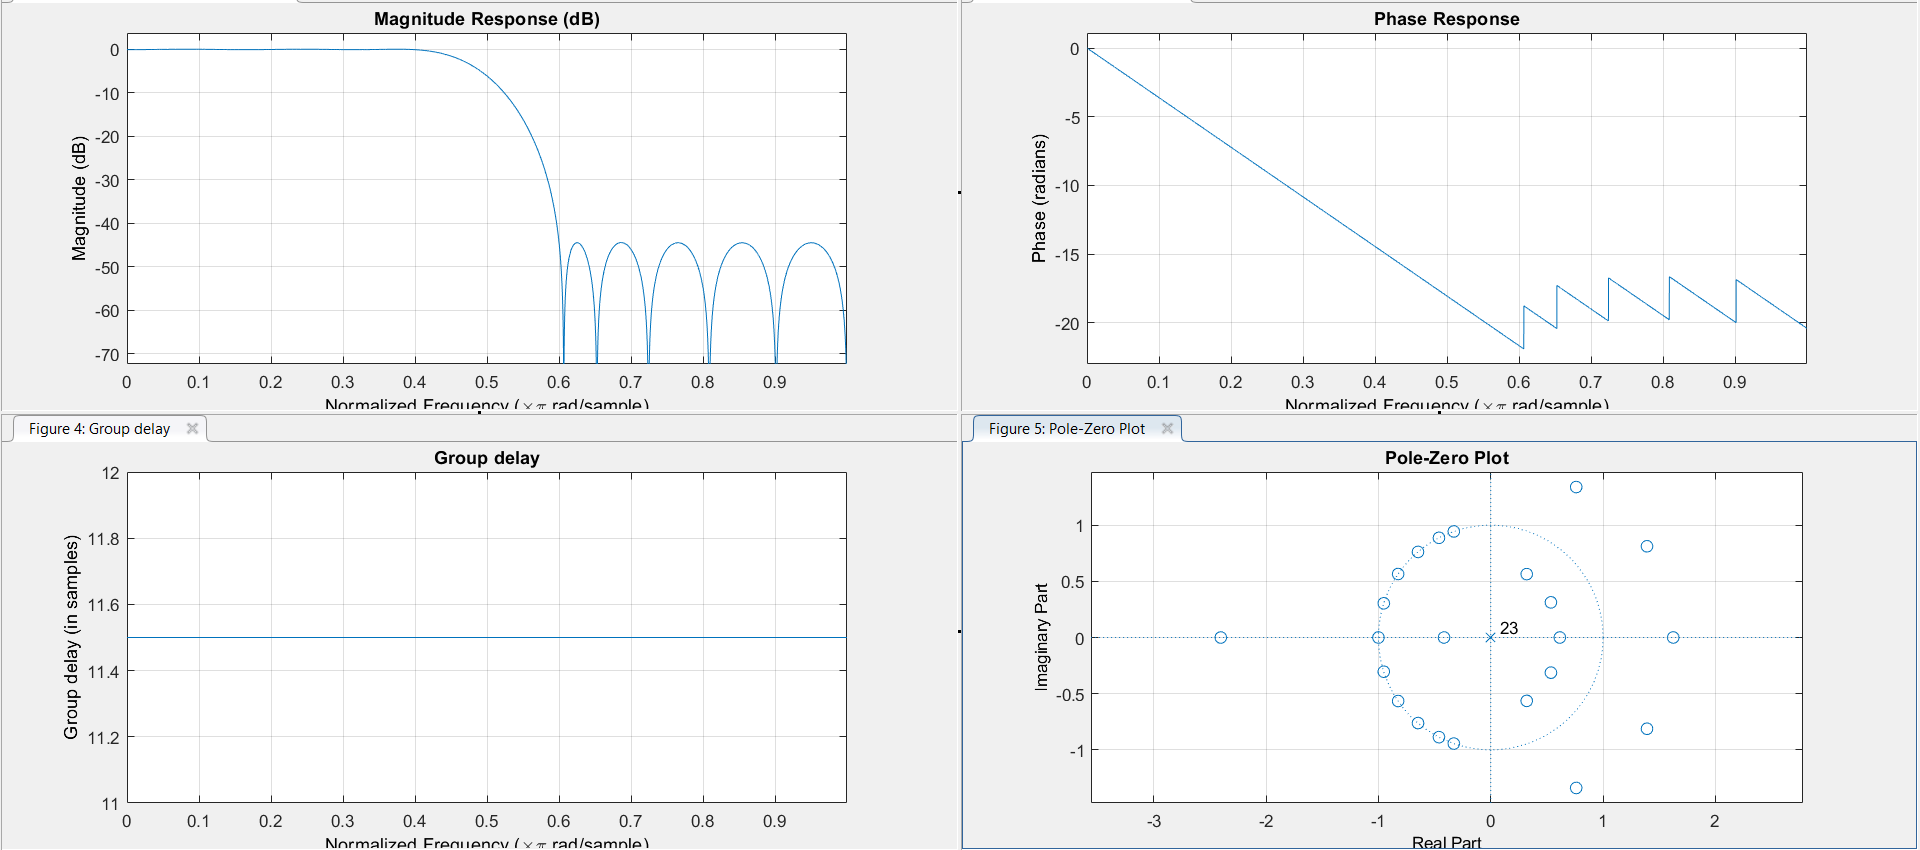

**Observations and Comments:**

We can observe that there are 23 zeroes and 1 pole at 0 of order 23. We can verify that there are no poles outside the unit circle, which confirms  that the system is stable, and there is no constraint of unit circle for the zeros.

We can observe that we obtain 0dB magnitude in passband, with the ripple provided and in the stop band the gain is attenuated to  -40dB.

Our phase plot is piecewise linear, as expected with discontinuties at 5 points.

- Give a comparison with the filter obtained using the windowing method above.  

           * ANSWER*

- In pole zero plot , we can observe that there is a difference between the coefficients obtained in windowing method and the min max method .

- In Magnitude Response , we can observe that the magnitudes in the stop bands are different in both cases .

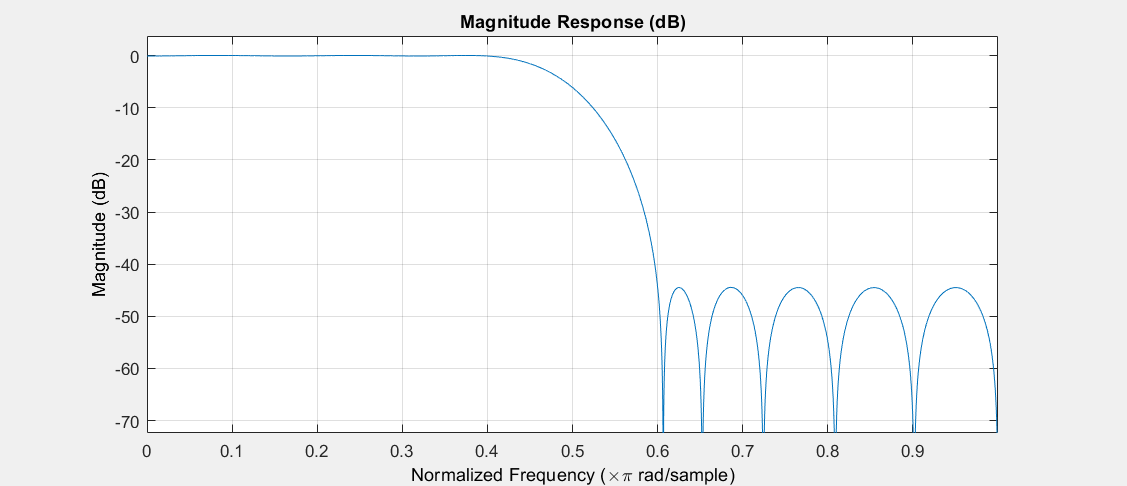

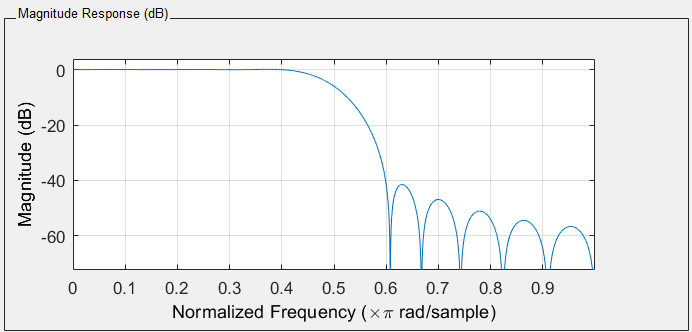

- In Phase response , both the cases have similar response in passband but we can observe that there is a difference in phase response in the stopband .

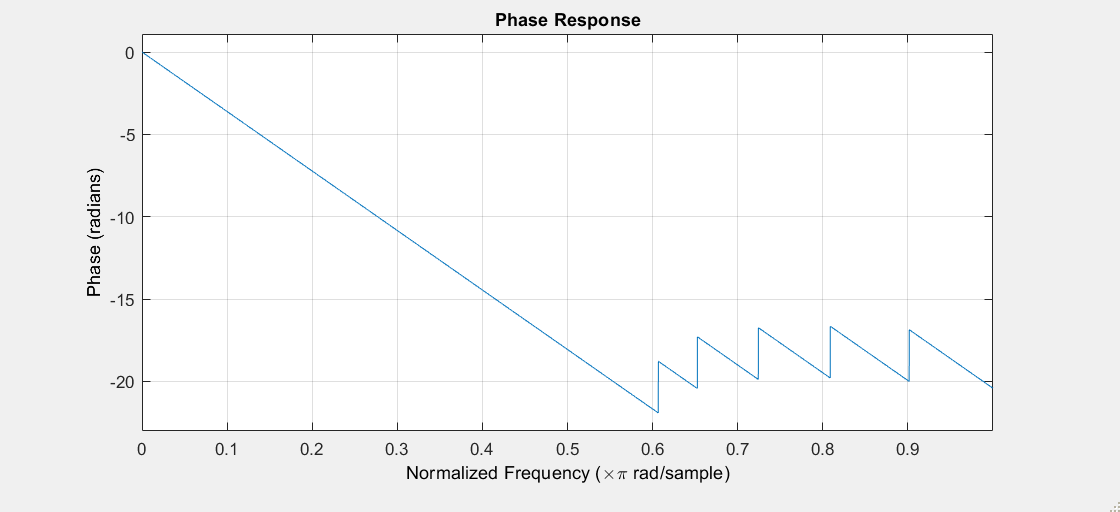

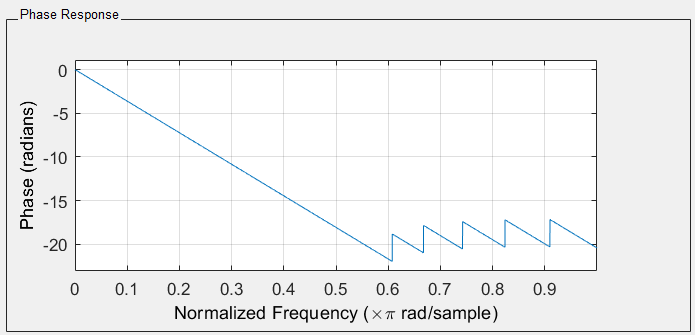

- The group delay remains the same for both the cases since M = 23 for both the cases.

## IIR Filter Design

In this part, we will solve Example 5 of Chapter 7 of Oppenheim and Schafer textbook using the *filterDesigner* tool. Although you need to know how impulse invariance and bilinear transform methods work, you almost never design discrete-time filters manually. Almost always, you will use some tools, such as *filterDesigner* MATLAB. 

**Note:**  From this course point of view, you should know how to manually design filters using impulse invariance and bilinear transform for IIR filters, and window and equiripple (also called as minimax or Parks-McClellan methods) for FIR filters. 

**References:** 

- Example 5 of Chapter 7 of Oppenheim and Shafer textbook, 3rd Edition (If you have the 2nd Edition, see Example 7.4, 7.5 and 7.6 for the IIR part starting from Page 458, and Section 7.5.1 on Page 503 for FIR part )

- [https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf](https://spinlab.wpi.edu/courses/ece503_2014/10-1intro_to_filter_design.pdf)

Design the following filter: $\delta_{p_1} = \delta_{p_2} = 0.01, \;\;
\delta_s = 0.001, \;\; \omega_p = 0.4\pi, \;\; \omega_s = 0.6\pi
$using

- IIR Butterworth

- IIR Chebyshev Type 1

- IIR Chebyshev Type 2

- FIR Window - Kaiser

and answer the following for each of the above methods: 

- Order of the filter

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

An example is shown below for IIR Butterworth filter: 

### IIR Butterworth filter

Open the Filter Designer tool, by typing *filterDesigner *in the command window as shown below. 

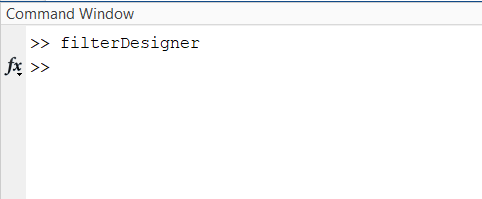

We first note that in the Filter Designer tool, for designing IIR filter,  it is assumed that $\delta_{p_1}=0
$ (red annotations in Fig. 1). Hence, in order to design the filter using this tool,  we first scale all the tolerance parameters, design the filter using the toolbox and then rescale them back.

- **Scaling the parameters:** Let $\delta_{p_1}',\; \delta_{p_2}'$and $\delta_s'$ be the new parameters.  We want to scale all the parameters according to the requirement that $\delta_{p_1}'=0$.  This implies, $1-\delta_{p_2}' = (1-\delta_{p_2})/(1+\delta_{p_1}) = (1-0.01)/1.01=  0.9802$. Hence, $\delta_{p_2}' = 1-0.9802=0.0198$. Similarly, $\delta_s' = \delta_s/(1+\delta_{p_1}) = 0.001/1.01 = 0.00099$. 

- **Filter Design:** Now, we feed these values in the Filter Designer tool  and design the filter (blue annotations in Fig. 1)

. 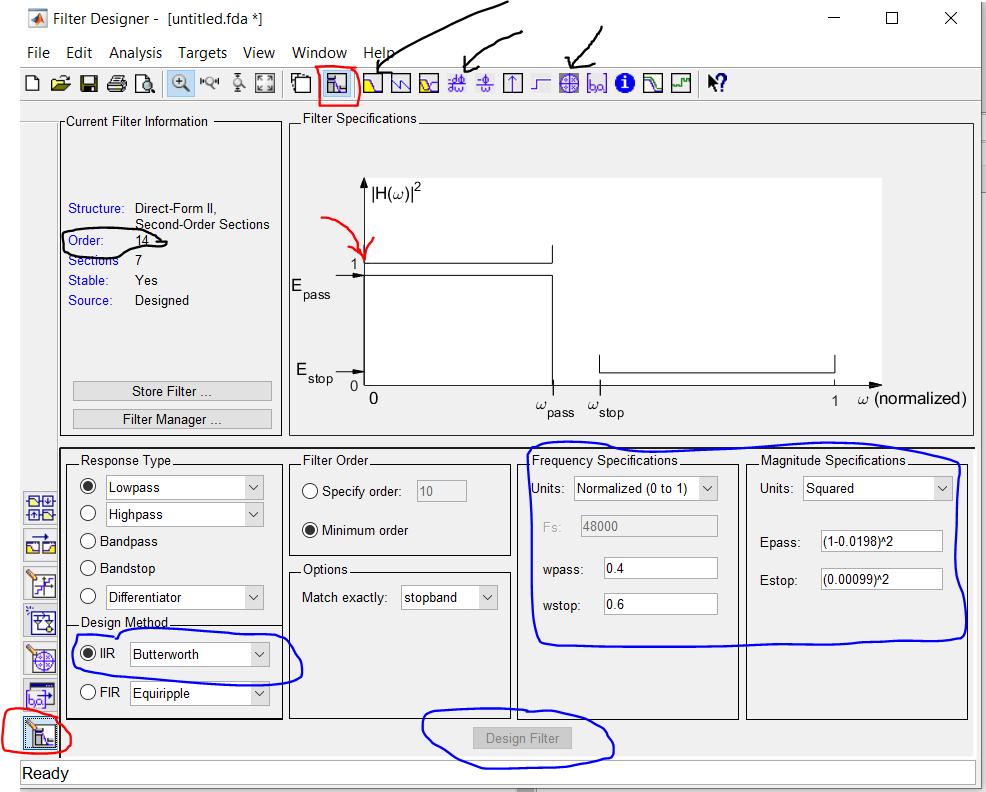

                                                      Fig 1: IIR Butterworth Filter Design

- **Rescaling parameters:**  Now, if you look at the magnitude response (by clicking on the tab besides the red annotated box), you can see that the above filter has gain of $0.9914$at $0.4\pi
$and $0.00099$at $0.6\pi$. Note that the design already satisfies the required specification. However, in some cases, if the required specification is not met, you need to rescale back the impulse response or numerator coefficients by $1+{\delta_{p_1}}$ to match the desired response. 

- **Filter Analysis: **Now, we will look at magnitude response, group delay and pole-zero plots and order of the filter (black annotations in Fig. 1). 

              - Filter order is 14. 

              - Both passband and stopbands have monotonic behaviour. 

              - There are 14 zeros at $-1$. Since all the poles are inside the unit circle, the filter is stable. 

              - The group delay is highest in the transition band and below 15 in the passband. 

          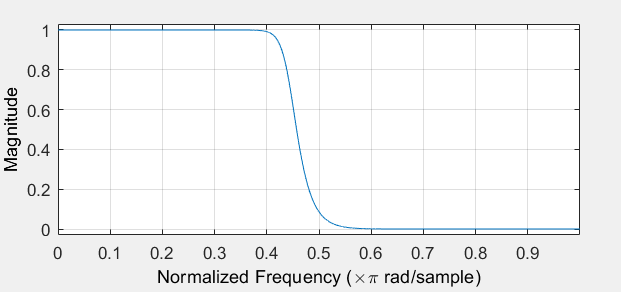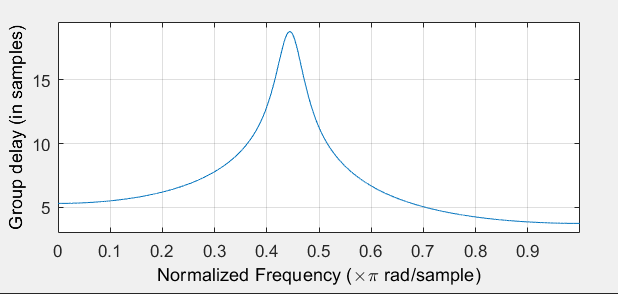

                               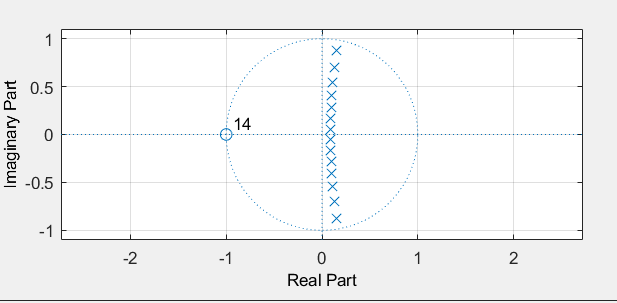

coeff_butterworth =    [1	2	1	1	-0.311481834615729	0.801350793047670
                        1	2	1	1	-0.260944972372310	0.509087788392416
                        1	2	1	1	-0.226920829568310	0.312320562148340
                        1	2	1	1	-0.203855290193414	0.178928745908718
                        1	2	1	1	-0.188569857893176	0.0905305713247072
                        1	2	1	1	-0.179218337938384	0.0364491899576411
                        1	2	1	1	-0.174773229676566	0.0107423961650365];

### IIR Chebyshev Type 1 

% Enter the filter coefficients

coeff_chebyshev1 =  [1	2	1	1	-0.546973251226029	0.898834056379833
                    1	2	1	1	-0.717257651116436	0.713657895463924
                    1	2	1	1	-1.01523783975706	0.548112152489310
                    1	2	1	1	-1.26265789161358	0.438338863184365];

Answer the following:

- Order of the filter

*            ANSWER: *8th order filter.

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER: *For Chebyshev Type 1, ripple is present in the passband and the stopband is monotonically decreasing .

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER: *

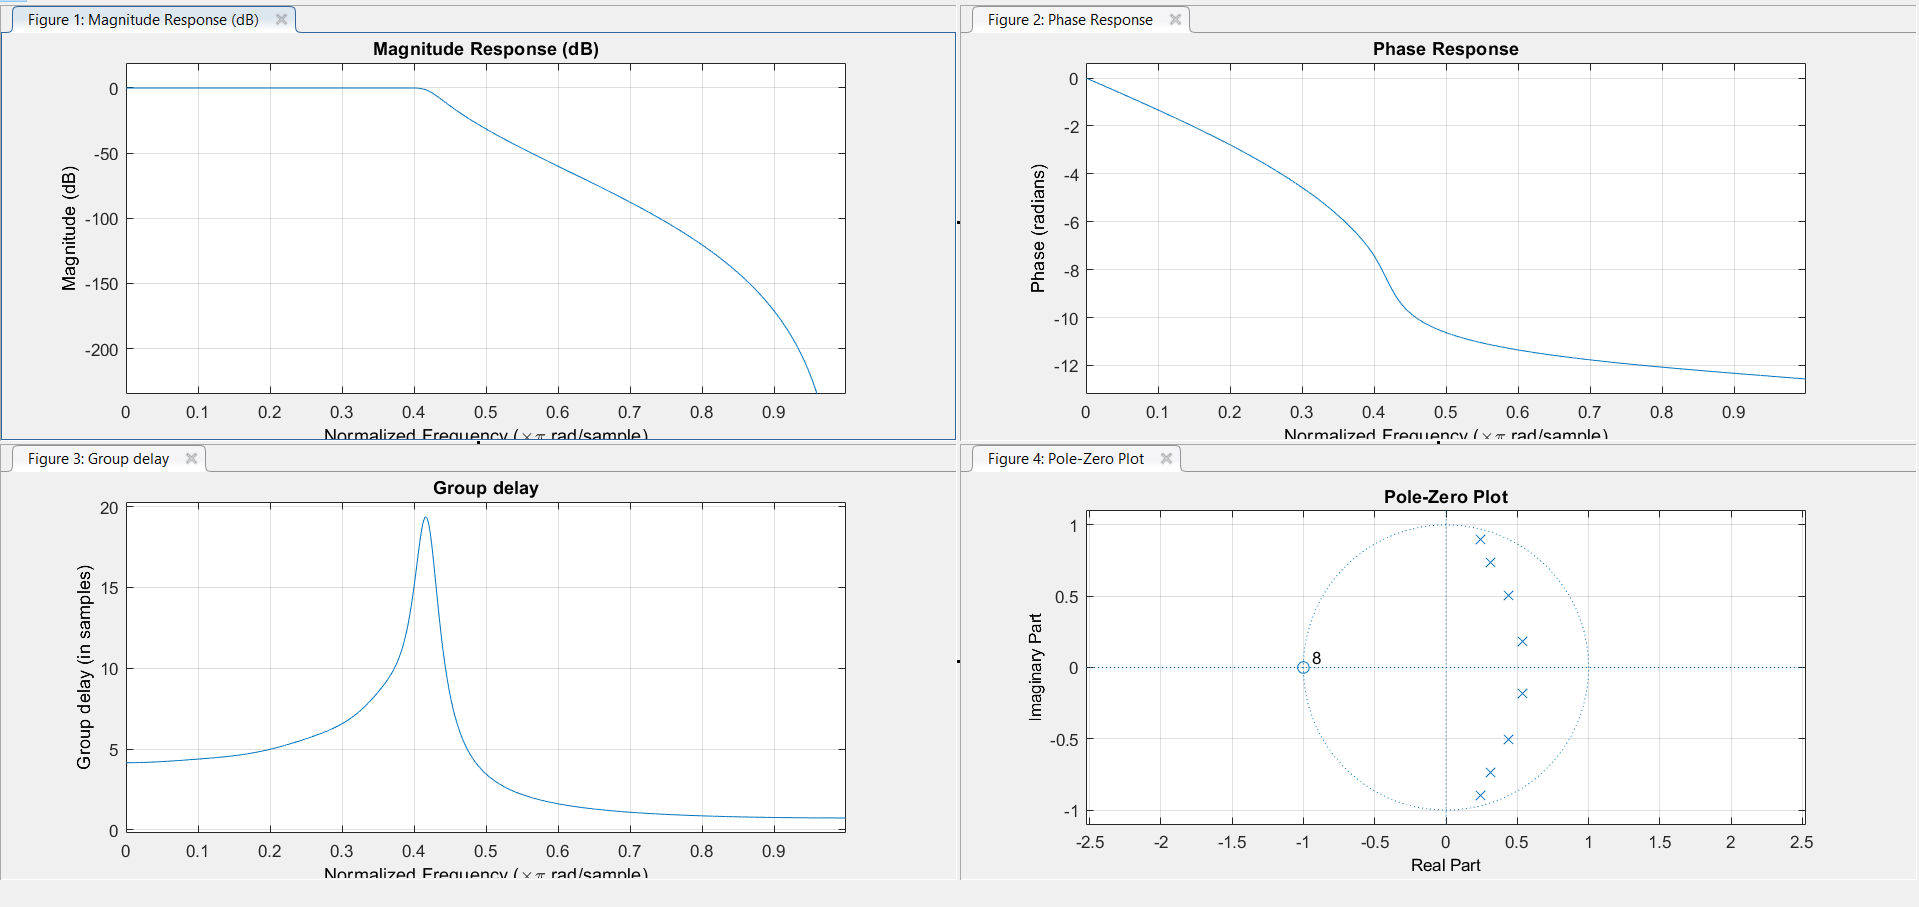

### IIR Chebyshev Type 2 

% Enter the filter coefficients

coeff_chebyshev2 = [1	0.652918507109619	1	1	-0.120507510600431	0.746181816416871
                    1	0.930543693580330	1	1	-0.00374235913859665	0.385595563398861
                    1	1.43958909021804	1	1	0.125444696672893	0.150772042799095
                    1	1.92122021958431	1	1	0.210144428408631	0.0280846983904862];

Answer the following:

- Order of the filter

*            ANSWER : *8th order chebyshev filter.

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER: *For Chebyshev Type 2 filter there is no ripple in passband and there is equiripple behaviour in the stopband

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER: *

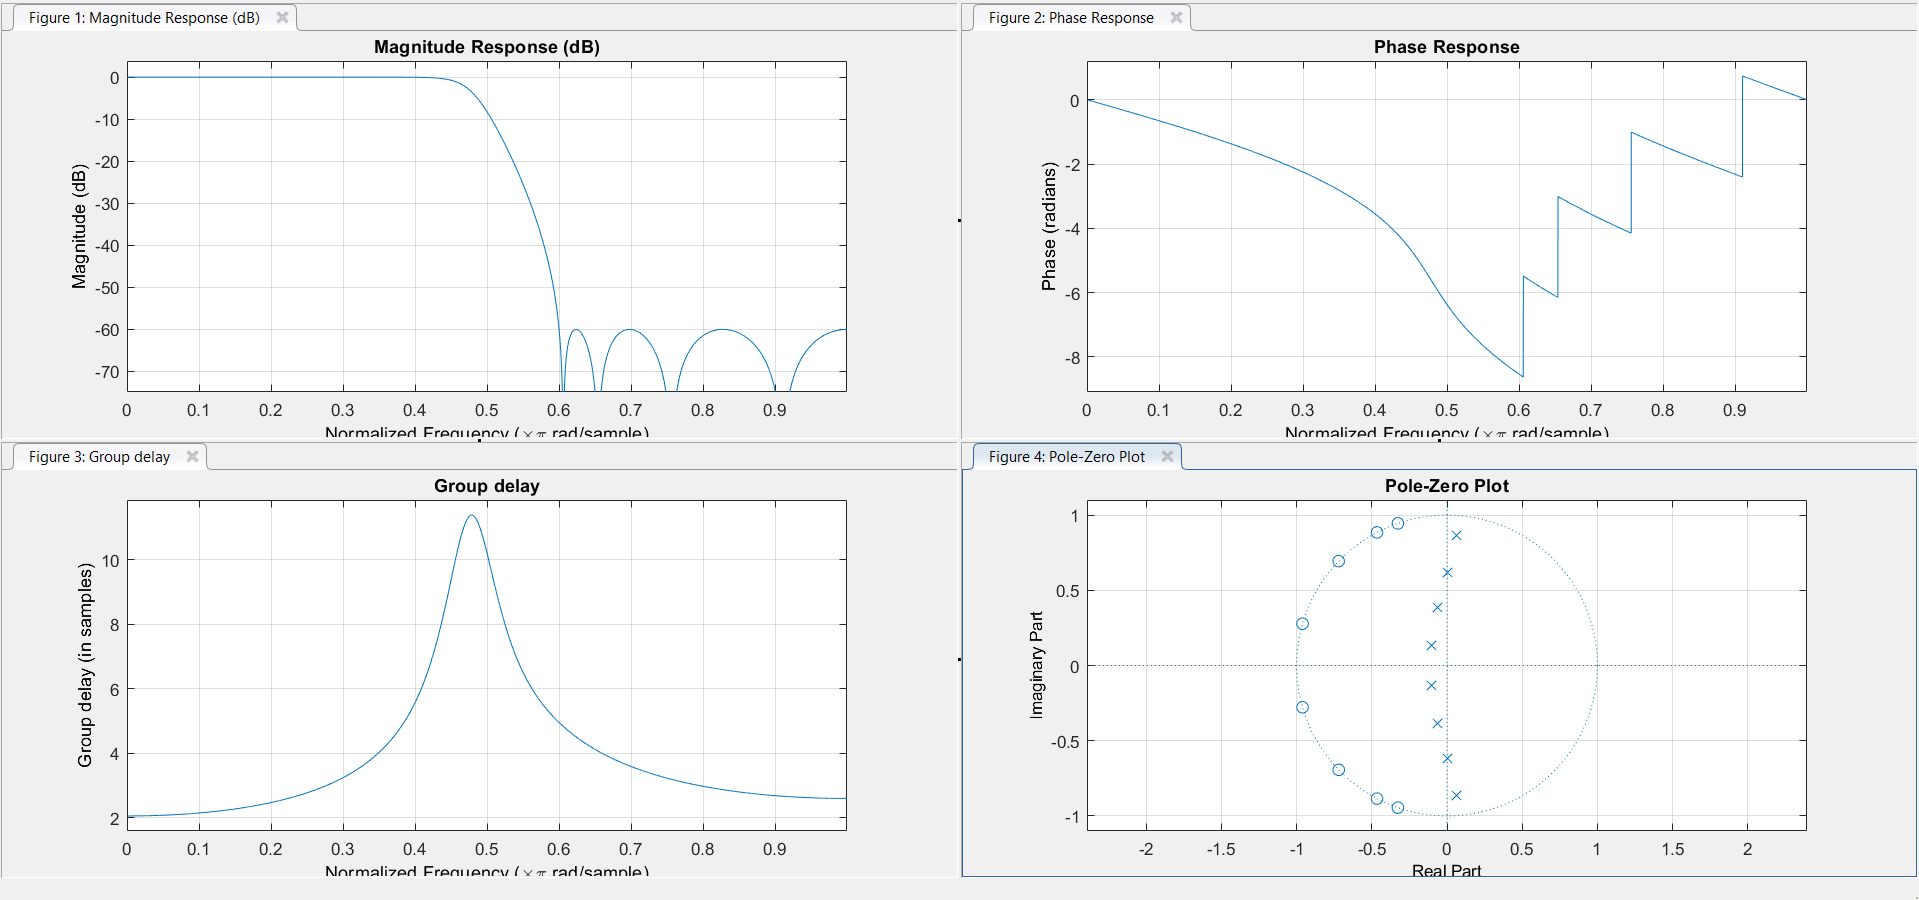

### FIR Window - Kaiser 

% Enter the filter coefficients

coeff_kaiser = [-0.000248008102503338	
                0.000533374457591009	
                0.000955506925690995	
                -0.00154968707202433	
                -0.00235608304490556	
                0.00342065549295198	
                0.00479681083291731	
                -0.00654832668496626	
                -0.00875444824748636	
                0.0115187774745581	
                0.0149850623958054	
                -0.0193662614808247	
                -0.0250010530838665	
                0.0324725189942208	
                0.0428854227839861	
                -0.0586188547145853	
                -0.0858846674984382	
                0.147517760688666	
                0.449241499883213	
                0.449241499883213	
                0.147517760688666	
                -0.0858846674984382	
                -0.0586188547145853	
                0.0428854227839861	
                0.0324725189942208	
                -0.0250010530838665	
                -0.0193662614808247	
                0.0149850623958054	
                0.0115187774745581	
                -0.00875444824748636	
                -0.00654832668496626	
                0.00479681083291731	
                0.00342065549295198	
                -0.00235608304490556	
                -0.00154968707202433	
                0.000955506925690995	
                0.000533374457591009	
                -0.000248008102503338];

Answer the following:

- Order of the filter

*            ANSWER: *37th order kaiser window FIR filter.

- A sentence on passband and stopband behaviour (in terms of monotonic and equiripple behaviour) 

*            ANSWER: *There is some amount of ripple in the passband and the stopband attenuaton is according to the specifications given.

- Copy and paste magnitude response, group delay and pole-zero plots and write your comments. 

*            ANSWER*

### 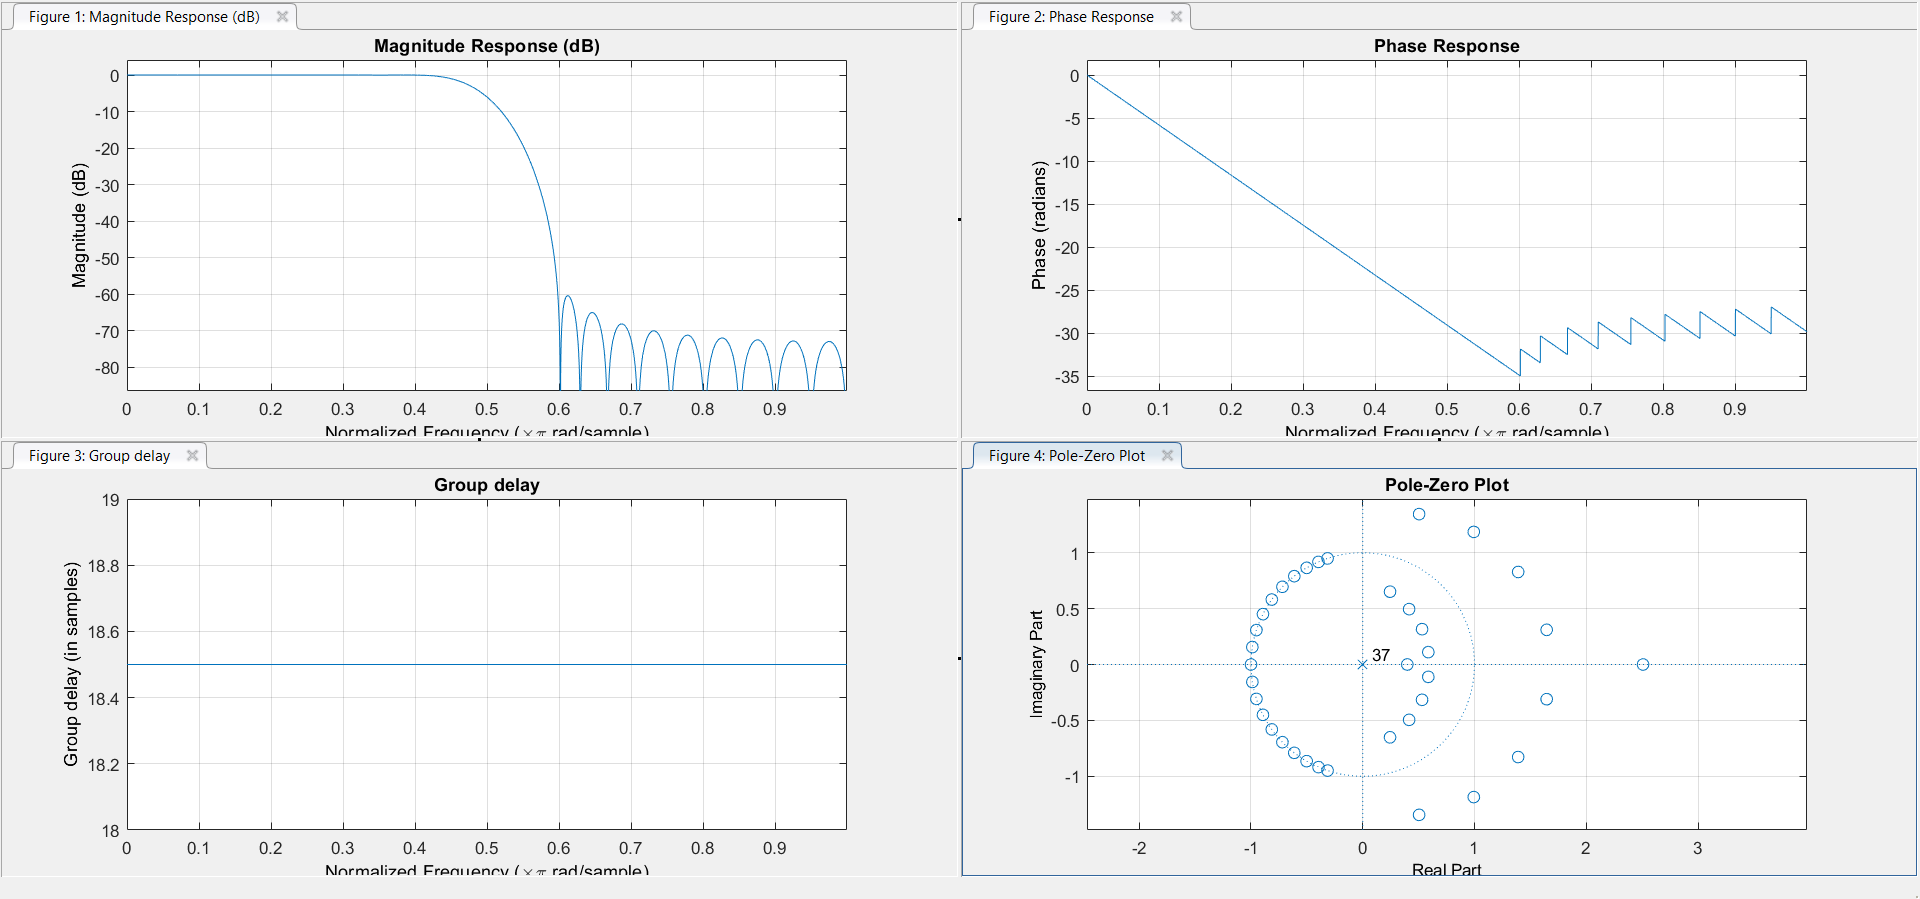

### Common Questions :

After all the filter designs are completed, answer the below questions. 

- Among IIR filters, which filter gives the lowest order? What is the practical use of having a lowest order filter (think in terms of number of multiplications in the implementation)? 

            *ANSWER: *Chebyshev type 1 and 2 gave the lowest order of the filter. The order of a filter also **indicates the minimum number of reactive components that the filter will require, **thus we need lowest possible order filter to design the most cost-efficient filter.

- Among the FIR filters, which method gives the lowest order? Compare this with orders of IIR filters. 

Kaiser window gives us filter design of the order 37, which is very high when compared to the IIR filter designs.

- For a given filter specification, if you want the filter order to be as small as possible, which implemetation would you choose, FIR or IIR? Which one among them? 

            *ANSWER  *For implementation, we use IIR filter design since it has comparably lower order of filter design.

- FIR filters are always stable, but IIR filters may or may not be stable (True or False)? 

            *ANSWER: *FIR impulse response is absolutely summable, since it is a finite valued response, whereas IIR impulse response might not be absolutely summable due to non-convergence of the sum.

- Comment on the group delays of FIR and IIR filters. Which design would you prefer (FIR or IIR) if the filter order is not important but a constant group delay is required? 

            *ANSWER: *FIR group delay is constant, whereas the IIR group delay is not constant and peaks at an instant. If constant group delay is required, we should use FIR filter only.

### Thank you!